Chapter 6

Interpolation & Curve Fitting

Example 6.1

Write down MATLAB codes using **“polyfit(x, y, n)”** and **“polyval(p, x)”** for the following data table, as (a)

and

(b)  $\left\lbrack \begin{array}{cccccc}
\;\;\;t & 10 & 15 & 20 & 22\ldotp 5 & 30\\
v\left(t\right) & 227 & 363 & 517 & 603 & 903
\end{array}\right\rbrack$

**(i).** Find the polynomial of least degree that incorporates all the values in the table. and estimate the velocities corresponding to $t=17,25$ and $30\;\textrm{seconds}$. **(ii).** Draw the figure showing fitted polynomial and the given points.

t = [10 15 20 22.5 30]; % time
v = [227 363 517 603 903]; % velocity
pt = polyfit(t,v,4) % coefficients of ploynomial

pt =    -0.0002    0.0240   -0.4267   28.2000  -34.2000


t1 = [17 25 30]; % given time t
v1 = polyval(pt,t1); % velocity at t
[t1', v1'] % velocity at corresponding time

ans =    17.0000  421.9875
   25.0000  695.8000
   30.0000  903.0000


 (ii) Plotting of velocity at corresponding time

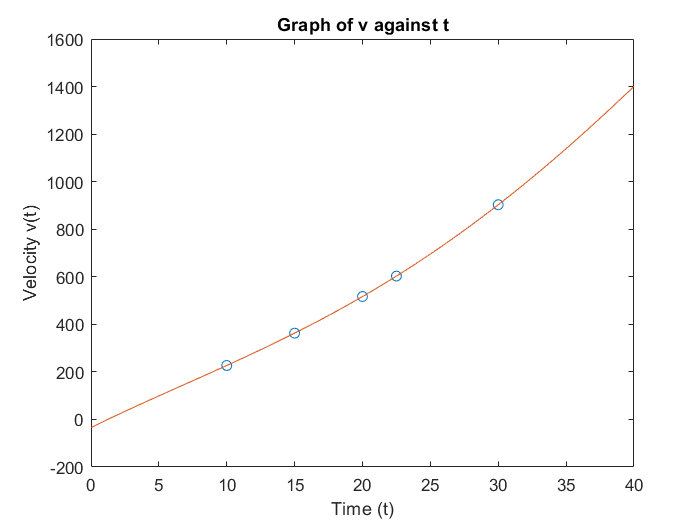

t2 = linspace(0, 40, 500); % generate 500 t
v2 = polyval(pt, t2); % corresponding v
plot(t,v,'o',t2,v2);
title('Graph of v against t');
xlabel('Time (t)');
ylabel('Velocity v(t)');

Example 6.2

Use MATLAB function lsqcurvefit(fun,a0, xdata,ydata) to fit the general form like$H=\frac{a_1 }{1+a_2 \exp \left(-a_3 t\right)}$

from the given data table, the height of a child is measured at different ages as


$$\left\lbrack \begin{array}{cccccc}
\;\;\;t\left(\mathrm{years}\right) & 3 & 6 & 9 & 12 & 15\\
H\left(\mathrm{feet}\right) & 2\ldotp 87 & 3\ldotp 60 & 4\ldotp 28 & 4\ldotp 88 & 5\ldotp 35
\end{array}\right\rbrack$$


td = [3 6 9 12 15]; % state time-values
hd = [2.87 3.60 4.28 4.88 5.35]; % staet height-values
Fd = @(a,td) a(1)./(1+a(2).*exp(-a(3).*td)); % define function
a0=[6,2,0.2]; % guess parameter values
% To fit the curve use MATLAB function lsqcurvefit with following syntax
a = lsqcurvefit(Fd,a0,td,hd) % value of a(1), a(2), and a(3)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


a =     6.4412    1.9536    0.1506


Chapter 7

Differentiation

Example 7.1

Find the derivative of $y=x^2 \sin \left(x\right)$

syms x
y = x^2*sin(x); % y
y1 = diff(y) % first derivative of y

$$y1 = x^{2}\,\cos\left(x\right)+2\,x\,\sin\left(x\right)$$

Example 7.2

Find the double derivative of $y=\mathrm{sin}\left(x\right)$

y2 = diff(y1) % second derivative of y

$$y2 = 2\,\sin\left(x\right)-x^{2}\,\sin\left(x\right)+4\,x\,\cos\left(x\right)$$

Chapter 8

Integration

Example 8.1

Find the integration of $y=\mathrm{sin}\left(x\right)$

clear all
syms x
y = sin(x); % y
inty = int(y) % integration of y

$$inty = -\cos\left(x\right)$$

Example 8.2

Evaluate the integration, $\int_0^{\pi } \sin \left(x\right)\textrm{dx}$

s_int = int(y,0,pi) % definite integration of y = sin(x)

$$s\_int = 2$$

Example 8.3

Evaluate the double integration, $\int_1^3 \int_0^{\pi } y\;\sin \left(\textrm{xy}\right)\textrm{dxdy}$

clear all
f1 = @(x,y) y.*sin(x.*y); % function
dbl_int = integral2(f1,0,pi,1,3) % double integration of function

dbl_int = 2.0000

Example 8.4

Evaluate the tripple integration, $\int_1^3 \int_0^{\pi } \int_0^1 \textrm{yz}\;\sin \left(\textrm{xy}\right)\textrm{dz}\;\textrm{dx}\;\textrm{dy}$

f2 = @(z,x,y) y.*z.*sin(x.*y); % function
trpl_int = integral3(f2,0,1,0,pi,1,3) % triple integration of function

trpl_int = 1.0000

Chapter 9

Ordinary Differential Equations

Example 9.1

Given that $\frac{\textrm{dy}}{\textrm{dx}}=2xy^2 -y$ , where $y=1$at $x=0$. Use MATLAB function “**[x1, y1] = ode23(f, [x0, xn], y0)**” 

**(i)** to estimate the values of $y$ in $0\le x\le 1\ldotp 4$ using $h=0\ldotp 2$ . (ii) to plot the solution curve in $\left\lbrack 0,1\ldotp 4\right\rbrack$.

% (i) solution
clear all
f = @(x,y) 2*x*y^2-y; % function f from y'= f(x,y)
[x1, y1] = ode23(f, [0:0.2:1.4], 1); % solution y for corresponding x between 0 to 1.4 with h 
Solution = [x1,y1]

Solution =          0    1.0000
    0.2000    0.8484
    0.4000    0.7644
    0.6000    0.7257
    0.8000    0.7275
    1.0000    0.7799
    1.2000    0.9253
    1.4000    1.3401


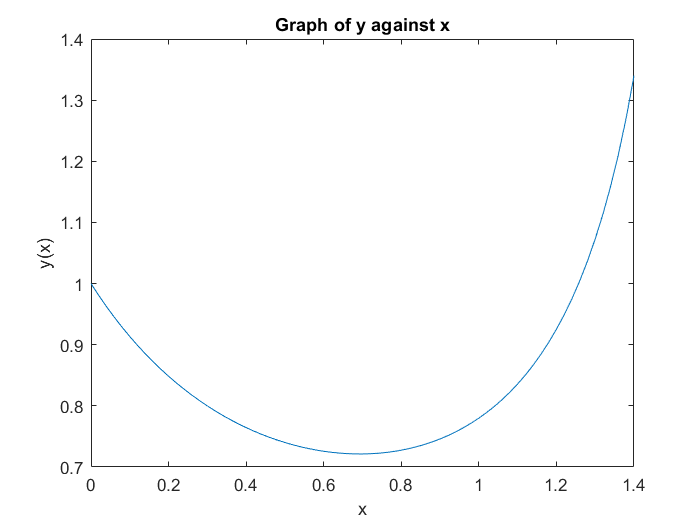

% (ii) Plotting of y(x)
xin = 0:0.02:1.4; % generate many points
[x2, y2] = ode23(f, xin, 1); % solution
plot(x2,y2);
title('Graph of y against x');
xlabel('x');
ylabel('y(x)');

Example 9.2

Consider the boundary value problem Use MATLAB function “**sol =**

bvp4c(odefun, bcfun, solinit)” to the BVP as** (i)** Estimate the values of y at $x=\frac{1}{3},\frac{2}{3},0\ldotp 4$ and $0\ldotp 9$. **(ii)** Plot the solution curve y.

% (i) solution
clear all
F = @(x,y) [y(2); 1+y(2)]; % dy/dx = F(x, y), rewritten as system, where 
bc = @(ya,yb) [ya(1)-1; yb(1)-2*(exp(1)-1)]; % format boundary values
solinit = bvpinit(linspace(0,1,3), [1,2]); % guess missing y at corresponding x
sol = bvp4c(F, bc, solinit); % solution
xint = [0, 1/3, 2/3, 1]; % input x, where y requred
sxint = deval(sol,xint); % find y at corresponding x
result = [xint',sxint(1,:)'] % publish result in proper format

result =          0    1.0000
    0.3333    1.4579
    0.6667    2.2283
    1.0000    3.4366


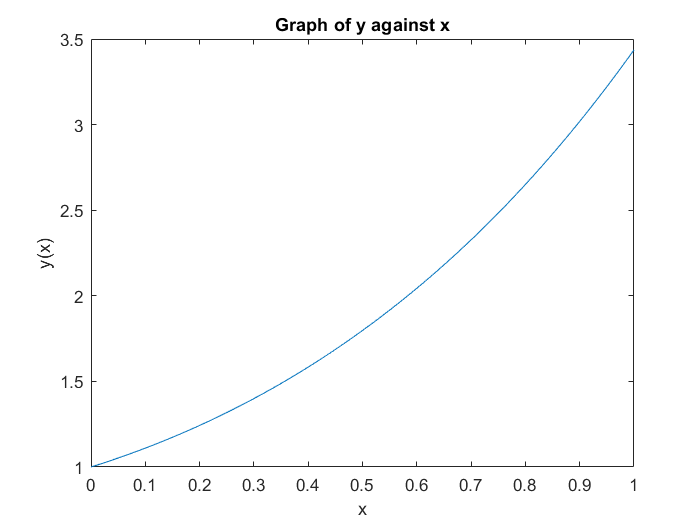

% (ii) Plotting of y(x)
xval = linspace(0,1); % generate many points
yval = deval(sol,xval); % find y at corresponding x
plot(xval, yval(1,:));
title('Graph of y against x');
xlabel('x');
ylabel('y(x)');

Example 9.3

Given the initial value problem $\frac{\textrm{dy}}{\textrm{dx}}=x+y^2 -z$ and $\frac{\textrm{dz}}{\textrm{dx}}x^2 -3y+\;z^2$ with $y\left(1\right)=2$ and $y\left(1\right)=2\ldotp 5$ Use MATLAB function “[x1, y1] = ode45(F, [x0, xn], y0)” **(i)** to estimate the values of y in using .

**(ii)** to plot the solution curve in $\left\lbrack 1,1\ldotp 4\right\rbrack$.

% (i) solution
clear all
F = @(x,y) [x+y(1)^2-y(2); x^2-3*y(1)+y(2)^2]; % defined function as x, y = y(1) and z = y(2)
[x1,yz] = ode45(F, [1:0.1:1.4], [2, 2.5]); % solution by ode45()
solyz = [x1,yz]

solyz =     1.0000    2.0000    2.5000
    1.1000    2.3091    2.6241
    1.2000    2.8009    2.7112
    1.3000    3.6825    2.6368
    1.4000    5.6417    2.0508


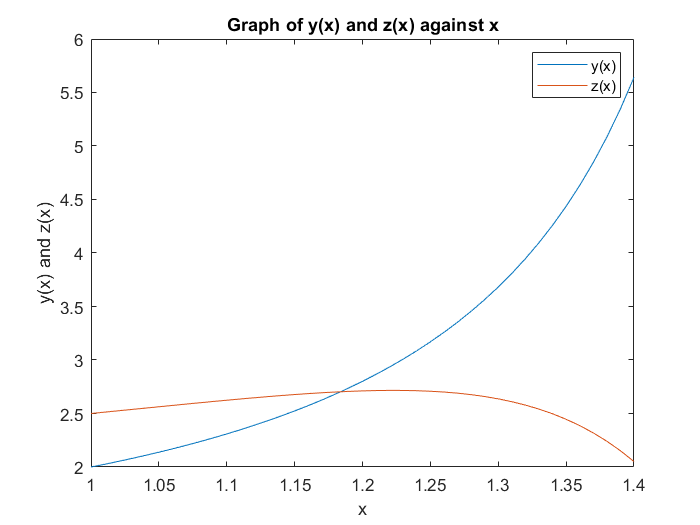

% (ii) Plotting of y(x) and z(x)
[x2,yz2] = ode45(F, [1:0.01:1.4], [2, 2.5]); % solutions at many points
plot(x2,yz2);
title('Graph of y(x) and z(x) against x');
xlabel('x');
ylabel('y(x) and z(x)');
legend('y(x)','z(x)');